% Load the neural network for the damped oscillator
load('net.mat')

load('test_data_damped_cell.mat');
load('test_data_damped.mat');

netDamped = net;

% Setting up plotting parameters
start_damped = 1;
numSimulations_damped = 10;
data_damped = test_data_damped_cell;

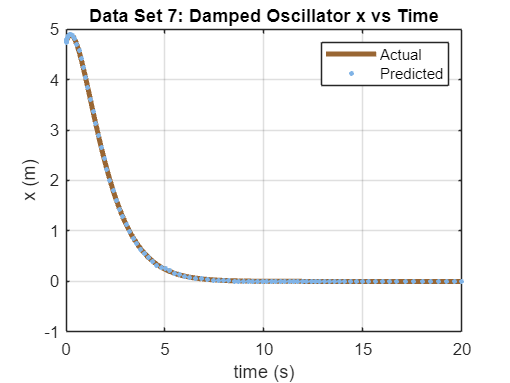

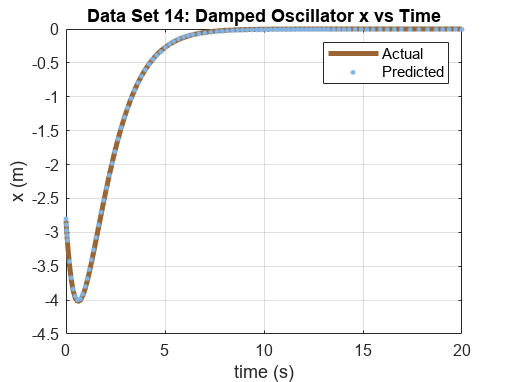

% Loop through the specified simulations for plotting
for i_damped = [7 14]%start_damped:numSimulations_damped
    % Extracting data for the current simulation
    time_damped = data_damped{i_damped, 1};
    x_damped = data_damped{i_damped, 2};

    
    % Transposing the data     
    inputX_damped = x_damped';


    % Making predictions using the neural network       
    predictedX_damped = predict(netDamped, {inputX_damped});

   
    % Converting predicted data to matrices   
    newPredictedX_damped = cell2mat(predictedX_damped);

    
    % Plotting x against Time
    figure;
    plot(time_damped, x_damped, 'color', [0.6, 0.4, 0.2], 'LineWidth', 3); 
    hold on;
    plot(time_damped, newPredictedX_damped, 'color', [0.5, 0.7, 0.9], 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 9);  


    xlabel('time (s)');
    ylabel('x (m)');
    title(['Data Set ', num2str(i_damped), ': Damped Oscillator x vs Time'])
    legend('Actual', 'Predicted');
    grid on;
    hold off;
    % Storing the current figure handle
    figHandles_x_Position{i_damped} = gcf;
end

% Saving all figures into a single MAT-file
save('DO_Trajectory_figures.mat', 'figHandles_x_Position');

% To load the figures:
% 1. Load the MAT-file
loadedData = load('DO_Trajectory_figures.mat');

% 2. Access the figure handles 

loadedFigHandles_x_Position = loadedData.figHandles_x_Position;

% 3. Display the figures
for i_damped = [7 14]%start_damped:numSimulations_damped
    
    figure(loadedFigHandles_x_Position{i_damped});
end